# Module 2 Video 2

## Detecting Moving Objects

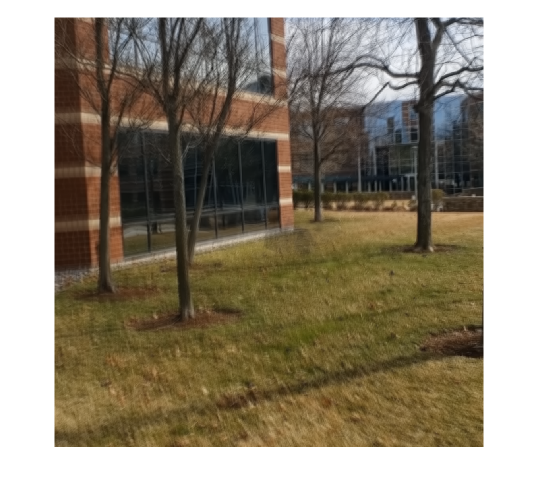

v = VideoReader("Turkey Video.mp4");

frameSum = im2double(read(v, 1));

for idx = 1:v.NumFrames
    frameSum = frameSum + im2double(read(v, idx));
end

avgFrame = frameSum/v.NumFrames;
background = avgFrame;

imshow(avgFrame)

% v2 = VideoWriter("MyTurkeyBoxed.mp4", "MPEG-4");
% open(v2);
% 
% for idx = 1:v.NumFrames
%     frame = read(v, idx);
% 
%     frame = im2double(frame);
%     frameDiff = abs(frame - background);
% 
%     bw = segmentTurkey(frameDiff);
% 
     props = regionprops("table", bw, "BoundingBox");
     turkeyBoxed = insertShape(frame, "Rectangle", props.BoundingBox, "LineWidth", 3, "Color", "red");
% 
%     writeVideo(v2, turkeyBoxed);
% end
% 
% close(v2);

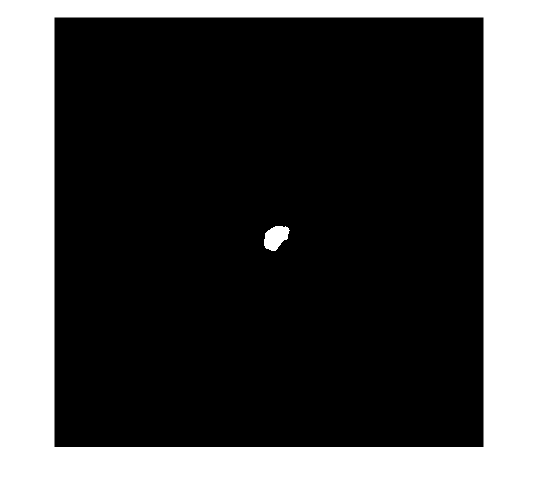

frame_290 = read(v, 290);
frame_290 = im2double(frame_290);
background = avgFrame;
frameDiff_290 = abs(frame_290 - background);

bw_290 = segmentTurkey(frameDiff_290);

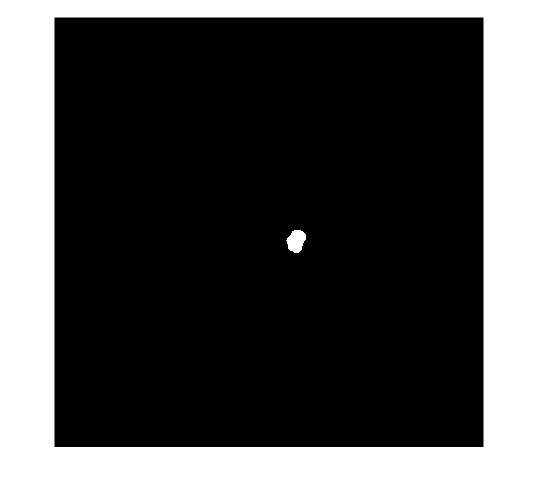

frame_19 = read(v, 19);
frame_19 = im2double(frame_19);
background = avgFrame;
frameDiff_19 = abs(frame_19 - background);

bw_19 = segmentTurkey(frameDiff_19);

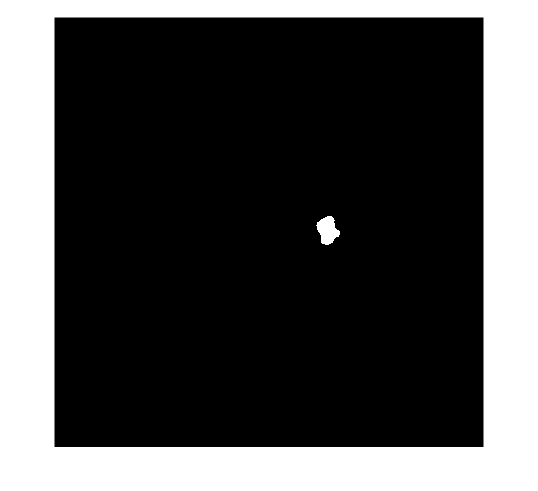

frame_690 = read(v, 690);
frame_690 = im2double(frame_690);
background = avgFrame;
frameDiff_690 = abs(frame_690 - background);

bw_690 = segmentTurkey(frameDiff_690);

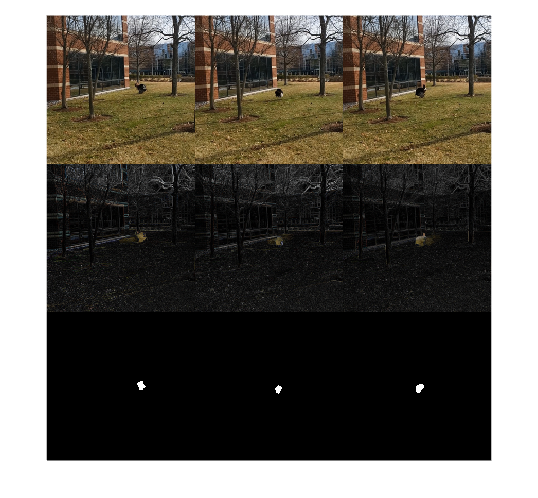

montage({frame_690, frame_19, frame_290, frameDiff_690, frameDiff_19, frameDiff_290, bw_690, bw_19, bw_290}, "Size", [3, 3])

function BW = segmentTurkey(X)

% Apply Gaussian filter
% X = imgaussfilt(X,1);

% Convert image to grayscale
X = im2gray(X);

% Adjust data to span data range
% X = imadjust(X);

% Threshold image - adaptive threshold
BW = imbinarize(X, 'adaptive', 'Sensitivity', 0.7, 'ForegroundPolarity', 'bright');

radius = 10;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Close mask with disk
radius = 15;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

BW = bwpropfilt(BW, 'Area', [2000, inf]);

% Fill holes
BW = imfill(BW, 'holes');

% Remove portions of the image that touch an outside edge
BW = imclearborder(BW);


end